user = 'fiore';
currentFolder = pwd;

addpath(strcat(pwd,'/lib/'))
addpath(strcat(pwd,'/lib/omnimorph-helper/'))
addpath(strcat(pwd,'/lib/math-helper/'))
addpath(strcat(pwd,'/plot/'))
addpath(strcat(pwd,'/res/'))

resFolder = fullfile(pwd, 'res'); 
outputFolder = 'figures';
W = 28;
H = 13;
m = 0.3;

run omnirotor_params.m


%   - k = 1 -> Brescianini formulation : no spin term in the moment part
%   - k = 2 -> Classical formulation : spin term in the moment part
k = 1;

if k == 1 
    load(fullfile(resFolder, 'All_Results_NoDrag.mat'), 'Results');
else
    load(fullfile(resFolder, 'All_Results_Complete.mat'), 'Results');
end
% Center of Mass Parameters
y = [0; 1; 0];  

CoM_all = [0*config.uavParams.L*y, ...
           0.2*config.uavParams.L*y, ...
           0.5*config.uavParams.L*y, ...
           1.0*config.uavParams.L*y, ...
           1.5*config.uavParams.L*y, ...
           2.0*config.uavParams.L*y];
Ncom = size(CoM_all, 2);

% Kinematics
R_B_Bcom = eye(3);         % Rotational matrix between B and B_com frames
d = config.system.com;     % Original CoM shift
T_B_Bcom = [R_B_Bcom -d; zeros(1,3) 1];

S = [ 1  -1  -1  1  1  -1  -1  1;
      1  1  -1  -1  1  1  -1  -1;
      1  1  1  1  -1  -1  -1  -1];

pi_B = config.uavParams.L * S;   %  Pi_B points in body frame

% Rotation matrices
Ri_B = eye(3);
Ri_Bcom = eye(3); 

% Matrix that applies CoM shift to all 8 vertices
M = ones(8,1);     

% Preallocation
pi_B_Bcom_all = zeros(3, 8, Ncom);
N_all = zeros(3, 8, Ncom);

for i = 1:Ncom

    % Shift all vertices by CoM offset along the chosen direction
    d_i = (M * CoM_all(:,i)')';   

    % Compute transformed vertices
    pi_B_Bcom_all(:,:,i) = R_B_Bcom * (pi_B - d_i);

end

for ic = 1 : Ncom
    vopt_ic = Results(ic).best_v;

    xy_opt_ic = reshape(vopt_ic, 2, 8);
    N_opt_ic  = normals_from_xy(xy_opt_ic);
    N_all(:,:,ic) = N_opt_ic;
end

J_in = config.uavParams.inertia;      
m_sys = config.system.mass;         
g = config.gravity;                  
g_vec = [0; 0; g];
J_inv = diag([1/J_in(1,1),1/J_in(2,2),1/J_in(3,3)]);
invInertia_mat = [eye(3)*(1/m_sys), zeros(3); zeros(3),J_inv];
np = config.uavParams.np;
cf = config.uavParams.c_f;
u_max = config.uavParams.maxPropSpeed;
u_min = -config.uavParams.minPropSpeed;
f_max = u_max^2*cf;
f_min = -u_min^2*cf;

disp('Trajectory');

Trajectory


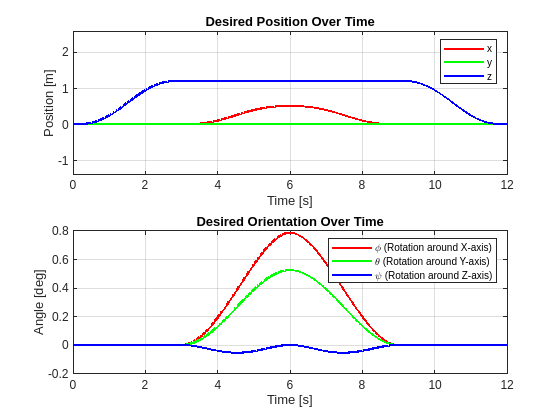

figure;
subplot(2,1,1);
plot(tdes,pdes(1,:),'r', 'LineWidth', 1.5);
hold on;
plot(tdes,pdes(2,:),'g', 'LineWidth', 1.5);
plot(tdes,pdes(3,:),'b', 'LineWidth', 1.5);
title("Desired Position Over Time")
legend("x ", ...
       "y", ...
       "z", ...
       "Location","northeast")
xlabel("Time [s]")
ylabel("Position [m]")
grid on;
axis equal

subplot(2,1,2);
eulerAngles = rotm2eul(Rdes,"ZYX"); %Euler
plot(tdes,eulerAngles(:,3),'r', 'LineWidth', 1.5);
hold on;
plot(tdes,eulerAngles(:,2),'g', 'LineWidth', 1.5);
plot(tdes,eulerAngles(:,1),'b', 'LineWidth', 1.5);
title("Desired Orientation Over Time")
legend("\phi (Rotation around X-axis)", ...
       "\theta (Rotation around Y-axis)", ...
       "\psi (Rotation around Z-axis)", ...
       "Location","northeast")
xlabel("Time [s]")
ylabel("Angle [deg]")
grid on

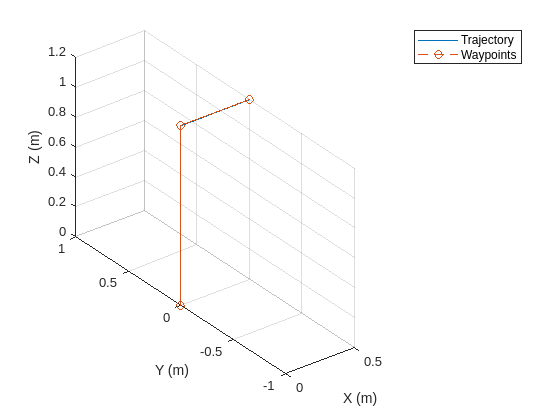

figure;
plot3(pdes(1,:),pdes(2,:),pdes(3,:), config.trajParams.wayPoints(1,:),config.trajParams.wayPoints(2,:),config.trajParams.wayPoints(3,:), "--o")
hold on;
xlabel("X (m)")
ylabel("Y (m)")
zlabel("Z (m)")
legend({"Trajectory", "Waypoints"})
grid on;
axis equal
view(3);

% 4. SIMULATION LOOP

num_scenarios = size(CoM_all, 2); 
idx_nominal = 1; 
dt = tdes(2) - tdes(1);
results = struct();
sim_data = struct();

combos = dec2bin(0:(2^np)-1) - '0'
U_poly = combos' * (f_max - f_min) + f_min;

% 1. LOOP SU TUTTI I CoM
for i = 1:num_scenarios
        
    CoM_curr = CoM_all(:, i);
        
    run omnirotor_params.m; 
    pdes_cg = pdes - CoM_curr; % pdes è la traiettoria del centro di massa
    wpt_cg = config.trajParams.wayPoints - CoM_curr;
    des = [pdes;vdes;ades;omd;domd;tdes];
    
    % ---------------------------------------------------------------------
    % CASO A: ADAPTIVE (Ottimizzato)
    % ---------------------------------------------------------------------
    pi_A = pi_B_Bcom_all(:,:,i); 
    N_A  = N_all(:,:,i);
    
    if k == 1, B_Plant_Real = AllocationMatrixBrescianini(N_A, pi_A);
    else,      B_Plant_Real = AllocationMatrixTilt(N_A, pi_A);
    end
    B_Controller_A = B_Plant_Real; 
    
    [h_p_A, h_v_A, h_w_A, h_err_p_A, h_R_err_A, h_R_A, h_u_rot_A, h_f_rot_A, h_W_des_A, h_W_real_A] = control_loop(B_Controller_A, B_Plant_Real, CoM_curr, des, Rdes, config);   
    

    sim_data(i).CoM = CoM_curr; 
    sim_data(i).A.p = h_p_A;
    sim_data(i).A.v = h_v_A;
    sim_data(i).A.w = h_w_A;
    sim_data(i).A.R = h_R_A;
    sim_data(i).A.err_p = h_err_p_A;
    sim_data(i).A.u_rot = h_u_rot_A;
    sim_data(i).A.f_rot = h_f_rot_A;
    sim_data(i).A.W_des = h_W_des_A;
    sim_data(i).A.W_real = h_W_real_A;

    % ---------------------------------------------------------------------
    % CASO B: FIXED NOMINAL (Non Ottimizzato per lo shift)
    % ---------------------------------------------------------------------
    N_B = N_all(:,:,idx_nominal);         
    pi_B = pi_B_Bcom_all(:,:,i);
    
    if k == 1, B_Controller_B = AllocationMatrixBrescianini(N_B, pi_B);
    else,      B_Controller_B = AllocationMatrixTilt(N_B, pi_B);
    end
    B_Plant_Real = B_Controller_B;
    
    [h_p_B, h_v_B, h_w_B, h_err_p_B, h_R_err_B, h_R_B, h_u_rot_B, h_f_rot_B, h_W_des_B, h_W_real_B] = control_loop(B_Controller_B, B_Controller_B, CoM_curr, des, Rdes, config);

    sim_data(i).B.p = h_p_B;
    sim_data(i).B.v = h_v_B;
    sim_data(i).B.w = h_w_B;
    sim_data(i).B.R = h_R_B;
    sim_data(i).B.err_p = h_err_p_B;
    sim_data(i).B.u_rot = h_u_rot_B;
    sim_data(i).B.f_rot = h_f_rot_B;
    sim_data(i).B.W_des = h_W_des_B;
    sim_data(i).B.W_real = h_W_real_B;

    % ---------------------------------------------------------------------
    % CASO C: FIXED (Non Ottimizzato per lo shift)
    % ---------------------------------------------------------------------
    N_C = N_all(:,:,idx_nominal);        
    pi_C = pi_B_Bcom_all(:,:,idx_nominal);  
    
    if k == 1, B_Controller_C = AllocationMatrixBrescianini(N_C, pi_C);
    else,      B_Controller_C = AllocationMatrixTilt(N_C, pi_C);
    end
    
    [h_p_C, h_v_C, h_w_C, h_err_p_C, h_R_err_C, h_R_C, h_u_rot_C, h_f_rot_C, h_W_des_C, h_W_real_C] = control_loop(B_Controller_C, B_Controller_B, CoM_curr, des, Rdes, config);

    sim_data(i).C.p = h_p_C;
    sim_data(i).C.v = h_v_C;
    sim_data(i).C.w = h_w_C;
    sim_data(i).C.R = h_R_C;
    sim_data(i).C.err_p = h_err_p_C;
    sim_data(i).C.u_rot = h_u_rot_C;
    sim_data(i).C.f_rot = h_f_rot_C;
    sim_data(i).C.W_des = h_W_des_C;
    sim_data(i).C.W_real = h_W_real_C;
    
    results.com_dist(i) = norm(CoM_curr);
    
    % RMSE
    results.R_rmse_A(i) = sqrt(mean(sum(h_R_err_A.^2, 1)));
    results.R_rmse_B(i) = sqrt(mean(sum(h_R_err_B.^2, 1)));
    results.R_rmse_C(i) = sqrt(mean(sum(h_R_err_C.^2, 1)));
    results.p_rmse_A(i) = sqrt(mean(sum(h_err_p_A.^2, 1)));
    results.p_rmse_B(i) = sqrt(mean(sum(h_err_p_B.^2, 1)));
    results.p_rmse_C(i) = sqrt(mean(sum(h_err_p_C.^2, 1)));
    
    % Energy
    results.energy_A(i) = sum(sum(h_u_rot_A.^2)) * dt;
    results.energy_B(i) = sum(sum(h_u_rot_B.^2)) * dt;
    results.energy_C(i) = sum(sum(h_u_rot_C.^2)) * dt;
    
    % Max Input
    results.max_u_A(i) = max(max(abs(h_u_rot_A)));
    results.max_u_B(i) = max(max(abs(h_u_rot_B)));
    results.max_u_C(i) = max(max(abs(h_u_rot_C)));
    results.max_f_A(i) = max(max(abs(h_f_rot_A)));
    results.max_f_B(i) = max(max(abs(h_f_rot_B)));
    results.max_f_C(i) = max(max(abs(h_f_rot_C)));

    % Condition Number
    results.cond_A(i) = cond(B_Controller_A);
    results.cond_B(i) = cond(B_Controller_B);
    results.cond_C(i) = cond(B_Controller_C);

    % Sigma min
    results.sigma_A(i) = min(svd(B_Controller_A));
    results.sigma_B(i) = min(svd(B_Controller_B));
    results.sigma_C(i) = min(svd(B_Controller_C));
    
    fprintf('Done.\n');
end

Simulazione Scenario 1 / 6 ... 

Simulating trajectory...


Simulating trajectory...


Simulating trajectory...


Done.


Simulazione Scenario 2 / 6 ... 

Simulating trajectory...


Simulating trajectory...


Simulating trajectory...


Done.


Simulazione Scenario 3 / 6 ... 

Simulating trajectory...


Simulating trajectory...


Simulating trajectory...


Done.


Simulazione Scenario 4 / 6 ... 

Simulating trajectory...


Simulating trajectory...


Simulating trajectory...


Done.


Simulazione Scenario 5 / 6 ... 

Simulating trajectory...


Simulating trajectory...


Simulating trajectory...


Done.


Simulazione Scenario 6 / 6 ... 

Simulating trajectory...


Simulating trajectory...


Simulating trajectory...


Done.


%save('simulation_full_comparison.mat', 'sim_data', 'results', 'CoM_all');

## 5. VISUALIZZAZIONE RISULTATI SIMULAZIONE

x = pdes(1,:);
y = pdes(2,:);
z = pdes(3,:);

for i = 1 : length(CoM_all)
    com_ic    = CoM_all(:,i);       
    dx = com_ic(1); dy = com_ic(2); dz = com_ic(3);
    eulerAngles_real_A = rotm2eul(sim_data(i).A.R,"ZYX"); 
    eulerAngles_real_B = rotm2eul(sim_data(i).B.R,"ZYX"); 
    eulerAngles_real_C = rotm2eul(sim_data(i).C.R,"ZYX"); 

    
    fig = figure('Name','Simulation Results','Color','w');
    sgtitle( ...
    sprintf(['Tracking -- CoM Shift: ' ...
             '$\\Delta x = %.3f$, $\\Delta y = %.3f$, $\\Delta z = %.3f$'], ...
             dx, dy, dz), ...
    'Interpreter','latex', ...
    'FontSize',12);
    subplot(3,2,1);
    hold on;
    plot(tdes, sim_data(i).A.p(1,:), 'r', 'LineWidth', 0.5); 
    plot(tdes, sim_data(i).B.p(1,:), 'g-.', 'LineWidth', 0.5);
    plot(tdes, sim_data(i).C.p(1,:), 'b--', 'LineWidth', 0.5); 
    xlim([0 tdes(end)]);
    plot(tdes, x, 'k--', 'LineWidth', 0.5); 
    ylabel('X [m]'); legend('x_A','x_B', 'x_C', 'x_{ref}', Location='bestoutside'); grid on; title('Position');
    
    subplot(3,2,3);
    hold on;
    plot(tdes, sim_data(i).A.p(2,:), 'r', 'LineWidth', 0.5); 
    plot(tdes, sim_data(i).B.p(2,:), 'g-.', 'LineWidth', 0.5); 
    plot(tdes, sim_data(i).C.p(2,:), 'b--', 'LineWidth', 0.5); 
    plot(tdes, y, 'k--', 'LineWidth', 0.5);
    xlim([0 tdes(end)]);
    ylabel('Y [m]'); legend('y_A','y_B', 'y_C', 'y_{ref}', Location='bestoutside'); grid on;
    
    subplot(3,2,5);
    hold on;
    plot(tdes, sim_data(i).A.p(3,:), 'r', 'LineWidth', 0.5); 
    plot(tdes, sim_data(i).B.p(3,:), 'g-.', 'LineWidth', 0.5); 
    plot(tdes, sim_data(i).C.p(3,:), 'b--', 'LineWidth', 0.5); 
    plot(tdes, z, 'k--', 'LineWidth', 0.5);
    xlim([0 tdes(end)]);
    ylabel('Z [m]'); legend('z_A','z_B', 'z_C', 'z_{ref}', Location='bestoutside'); grid on;
    subplot(3,2,2);
    hold on;
    plot(tdes, eulerAngles_real_A((1:length(tdes)),3), 'r', 'LineWidth', 0.5);
    plot(tdes, eulerAngles_real_B((1:length(tdes)),3), 'g-.', 'LineWidth', 0.5);
    plot(tdes, eulerAngles_real_C((1:length(tdes)),3), 'b--', 'LineWidth', 0.5);
    plot(tdes, eulerAngles(:,3),'k--', 'LineWidth', 0.5); xlim([0 tdes(end)]);
    ylabel('\phi [rad]'); legend('\phi_A','\phi_B', '\phi_C', '\phi_{ref}', Location='bestoutside'); grid on; title('Orientation');
    
    subplot(3,2,4);
    hold on;
    plot(tdes, eulerAngles_real_A((1:length(tdes)),2), 'r', 'LineWidth', 0.5);
    plot(tdes, eulerAngles_real_B((1:length(tdes)),2), 'g-.', 'LineWidth', 0.5);
    plot(tdes, eulerAngles_real_C((1:length(tdes)),2), 'b--', 'LineWidth', 0.5);
    plot(tdes, eulerAngles(:,2),'k--', 'LineWidth', 0.5); xlim([0 tdes(end)]);
    ylabel('\theta [rad]'); legend('\theta_A','\theta_B', '\theta_C', '\theta_{ref}', Location='bestoutside'); grid on; 
    
    subplot(3,2,6);
    hold on;
    plot(tdes, eulerAngles_real_A((1:length(tdes)),1), 'r', 'LineWidth', 0.5);
    plot(tdes, eulerAngles_real_B((1:length(tdes)),1), 'g-.', 'LineWidth',0.5);
    plot(tdes, eulerAngles_real_C((1:length(tdes)),1), 'b--', 'LineWidth', 0.5);
    plot(tdes, eulerAngles(:,1),'k--', 'LineWidth', 0.5); xlim([0 tdes(end)]);
    ylabel('\psi [rad]'); legend('\psi_A','\psi_B', '\psi_C', '\psi_{ref}', Location='bestoutside'); grid on;
    
    set(fig, 'PaperUnits','centimeters', 'PaperSize', [W H], ...
                 'PaperPosition',[m m W-2*m H-2*m]);
    fileName = fullfile(outputFolder, sprintf('Tracking_CoM_%d.pdf',i));
    print(fig, fileName, '-dpdf', '-vector');    
end

for i = 1 : length(CoM_all)
    fig = figure('Name','Comanded Propeller Speed','Color','w');
    com_ic    = CoM_all(:,i);       
    dx = com_ic(1); dy = com_ic(2); dz = com_ic(3);
    sgtitle( ...
    sprintf(['Comanded Propeller Speed -- CoM Shift: ' ...
             '$\\Delta x = %.3f$, $\\Delta y = %.3f$, $\\Delta z = %.3f$'], ...
             dx, dy, dz), ...
    'Interpreter','latex', ...
    'FontSize',12);
    subplot(1,3,1)
    plot(tdes, sim_data(i).A.u_rot'); hold on;
    % plot(tdes, config.uavParams.maxPropSpeed ^2 * ones(size(tdes)), 'k--', 'LineWidth', 1.5);
    % plot(tdes, -config.uavParams.minPropSpeed ^2 * ones(size(tdes)), 'k--', 'LineWidth', 1.5);
    title('Case A ');
    xlabel('Time [s]'); ylabel('u_{rot} [Hz^2]');grid on;xlim([0 tdes(end)]);
    subplot(1,3,2)
    plot(tdes, sim_data(i).B.u_rot'); hold on;
    % plot(tdes, config.uavParams.maxPropSpeed ^2 * ones(size(tdes)), 'k--', 'LineWidth', 1.5);
    % plot(tdes, -config.uavParams.minPropSpeed ^2 * ones(size(tdes)), 'k--', 'LineWidth', 1.5);
    title('Case B ');
    xlabel('Time [s]'); ylabel('u_{rot} [Hz^2]'); grid on;xlim([0,tdes(end)]);
    subplot(1,3,3)
    plot(tdes, sim_data(i).C.u_rot'); hold on;
    % plot(tdes, config.uavParams.maxPropSpeed ^2 * ones(size(tdes)), 'k--', 'LineWidth', 1.5);
    % plot(tdes, -config.uavParams.minPropSpeed ^2 * ones(size(tdes)), 'k--', 'LineWidth', 1.5);
    title('Case C ');
    xlabel('Time [s]'); ylabel('u_{rot} [Hz^2]'); grid on;xlim([0,tdes(end)]);

    set(fig, 'PaperUnits','centimeters', 'PaperSize', [W H], ...
                 'PaperPosition',[m m W-2*m H-2*m]);
    fileName = fullfile(outputFolder, sprintf('Prop_Speed_CoM_%d.pdf',i));
    print(fig, fileName, '-dpdf', '-vector');

    fig = figure('Name','Motor Thrust','Color','w');
    sgtitle( ...
    sprintf(['Motor Thrust -- CoM Shift: ' ...
             '$\\Delta x = %.3f$, $\\Delta y = %.3f$, $\\Delta z = %.3f$'], ...
             dx, dy, dz), ...
    'Interpreter','latex', ...
    'FontSize',12);
    subplot(1, 3, 1)
    plot(tdes, sim_data(i).A.f_rot'); hold on;
    % plot(tdes, f_max * ones(size(tdes)), 'k--', 'LineWidth', 1.5);
    % plot(tdes, f_min * ones(size(tdes)), 'k--', 'LineWidth', 1.5);
    title('Case A');
    xlabel('Time [s]'); ylabel('f_{rot} [N]');
    grid on;xlim([0,tdes(end)]);
    subplot(1, 3, 2)
    plot(tdes, sim_data(i).B.f_rot'); hold on;
    % plot(tdes, f_max * ones(size(tdes)), 'k--', 'LineWidth', 1.5);
    % plot(tdes, f_min * ones(size(tdes)), 'k--', 'LineWidth', 1.5);
    title('Case B');
    xlabel('Time [s]'); ylabel('f_{rot} [N]');grid on; xlim([0,tdes(end)]);
    subplot(1,3, 3)
    plot(tdes, sim_data(i).C.f_rot'); hold on;
    % plot(tdes, f_max * ones(size(tdes)), 'k--', 'LineWidth', 1.5);
    % plot(tdes, f_min * ones(size(tdes)), 'k--', 'LineWidth', 1.5);
    title('Case C');
    xlabel('Time [s]'); ylabel('f_{rot} [N]');grid on; xlim([0,tdes(end)]);

    set(fig, 'PaperUnits','centimeters', 'PaperSize', [W H], ...
                 'PaperPosition',[m m W-2*m H-2*m]);
    fileName = fullfile(outputFolder, sprintf('Prop_Thrust_CoM_%d.pdf',i));
    print(fig, fileName, '-dpdf', '-vector');
end

%% Plot Omnirotor Configuration
figure;
hold on;
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Omnirotor Configuration');
propeller_coordinates = zeros(3, np);
pi_sim  = pi_B_Bcom_all(:,:,i);
CoM_sim = CoM_all(:,i);
N_sim = N_all(:,:,i);
for j = 1:np
    propeller_coordinates(:,j) =  pi_sim(:,j) + CoM_sim;
end

plot3(propeller_coordinates(1,:), propeller_coordinates(2,:), propeller_coordinates(3,:), 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
plot3(CoM_sim(1,1), CoM_sim(2,1), CoM_sim(3,1), 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r'); % Plot COM
plot3(0,0,0, 'bo', 'MarkerSize', 5, 'MarkerFaceColor', 'b'); % Plot CG

cube_vertices = pi_sim' + CoM_sim';
edges = [
        1 2; 2 3; 3 4; 4 1;  
        5 6; 6 7; 7 8; 8 5;  
        1 5; 2 6; 3 7; 4 8   
    ];
for j = 1:size(edges, 1)
    plot3(cube_vertices(edges(j,:), 1), cube_vertices(edges(j,:), 2), ...
          cube_vertices(edges(j,:), 3), 'k--', ...
          'LineWidth', 0.5);
end

for j = 1:np
    
    rotor_pos_body = propeller_coordinates(:, j); 
    
    plot3([CoM_sim(1,1), rotor_pos_body(1)], ...
          [CoM_sim(2,1), rotor_pos_body(2)], ...
          [CoM_sim(3,1), rotor_pos_body(3)], 'Color', [0.6 0.6 0.6], ...
           'LineWidth', 0.5,'LineStyle', '--');
   
    n_vec_body = N_sim(:, j);
    
    n_vec_world = eye(3) * n_vec_body;
    arrow_length = 0.05;
    quiver3(rotor_pos_body(1), rotor_pos_body(2), rotor_pos_body(3), ...
            n_vec_world(1)*arrow_length, ...
            n_vec_world(2)*arrow_length, ...
            n_vec_world(3)*arrow_length, 'r', 'LineWidth', 1);
    
    basis_plane = null(n_vec_world');
    R_propeller_recon = [basis_plane, n_vec_world];
    theta_1 = linspace(0, 2*pi, 40);
    radius = 0.03;
    circle_points_local = radius * [cos(theta_1); sin(theta_1); zeros(1,40)];
    
    circle_points_world = rotor_pos_body + R_propeller_recon * circle_points_local;
    
    plot3(circle_points_world(1,:), circle_points_world(2,:), circle_points_world(3,:), 'k');
    
end
view(3);

%% Animation
num_frames = size(hist_p, 2);

fig_anim = figure('Name', 'Animation', 'Color', 'w');
hold on; grid on; axis equal;
xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
title('Omnirotor Trajectory Animation');
view(3);
videoFileName = 'drone_trajectory_opt_geometry.avi';
writerObj = VideoWriter(videoFileName, 'Motion JPEG AVI');
writerObj.FrameRate = 20; % Adjust frame rate (es. 1/dt se vuoi real time)
open(writerObj);
step_stride = 10; 
for m = 1:step_stride:num_frames
    
    cla;     
    curr_pos = hist_p(:, m);
    curr_R   = hist_R(:, :, m);    
    plot3(pdes(1,:), pdes(2,:), pdes(3,:), 'k--', 'LineWidth', 0.5);
    plot3(hist_p(1, 1:m), hist_p(2, 1:m), hist_p(3, 1:m), 'b-', 'LineWidth', 1);    
    plot3(curr_pos(1), curr_pos(2), curr_pos(3), 'ro', 'MarkerSize', 3, 'MarkerFaceColor', 'r');    
    
    for j = 1:config.uavParams.np
        
        p_motor_body = pi_sim(:, j) + CoM_sim;        
        p_motor_world = curr_pos + curr_R * p_motor_body;        
        plot3([curr_pos(1), p_motor_world(1)], ...
              [curr_pos(2), p_motor_world(2)], ...
              [curr_pos(3), p_motor_world(3)], '--k', 'LineWidth', 1);
        cube_vertices = curr_pos + curr_R*(pi_sim + CoM_sim);
        edges = [
                1 2; 2 3; 3 4; 4 1;  
                5 6; 6 7; 7 8; 8 5;  
                1 5; 2 6; 3 7; 4 8   
            ];
        for k = 1:size(edges, 1)
            p1 = cube_vertices(:, edges(k,1));
            p2 = cube_vertices(:, edges(k,2));
            
            plot3([p1(1) p2(1)], [p1(2) p2(2)], [p1(3) p2(3)], ...
                  'k--', 'LineWidth', 0.5); 
        end
          
        n_vec_body = N_sim(:, j);
        n_vec_world = curr_R * n_vec_body;        
        arrow_scale = 0.005;
        quiver3(p_motor_world(1), p_motor_world(2), p_motor_world(3), ...
                n_vec_world(1)*arrow_scale, ...
                n_vec_world(2)*arrow_scale, ...
                n_vec_world(3)*arrow_scale, 'r', 'LineWidth', 1.5, 'MaxHeadSize', 0.5);       

        n_vec = n_vec_world / norm(n_vec_world);
        if abs(n_vec(1)) < 0.9
            h = [1; 0; 0];
        else
            h = [0; 1; 0];
        end
        
        u = cross(n_vec, h);
        u = u / norm(u);         
        v = cross(n_vec, u);
        v = v / norm(v);        
        plane_basis = [u, v];        
        th = linspace(0, 2*pi, 30);
        disk_radius = 0.05;
        circle_2d = disk_radius * [cos(th); sin(th)];        
        circle_3d = p_motor_world + plane_basis * circle_2d;        
        plot3(circle_3d(1,:), circle_3d(2,:), circle_3d(3,:), 'g', 'LineWidth', 1);
        
    end
    
    axis_len = 0.15;
    x_axis = curr_pos + curr_R * [axis_len; 0; 0];
    y_axis = curr_pos + curr_R * [0; axis_len; 0];
    z_axis = curr_pos + curr_R * [0; 0; axis_len];    
    plot3([curr_pos(1) x_axis(1)], [curr_pos(2) x_axis(2)], [curr_pos(3) x_axis(3)], 'r-', 'LineWidth', 1); % X
    plot3([curr_pos(1) y_axis(1)], [curr_pos(2) y_axis(2)], [curr_pos(3) y_axis(3)], 'g-', 'LineWidth', 1); % Y
    plot3([curr_pos(1) z_axis(1)], [curr_pos(2) z_axis(2)], [curr_pos(3) z_axis(3)], 'b-', 'LineWidth', 1); % Z    
    axis tight; 
    buffer = 0.5;
    xlim([curr_pos(1)-buffer, curr_pos(1)+buffer]);
    ylim([curr_pos(2)-buffer, curr_pos(2)+buffer]);
    zlim([curr_pos(3)-buffer, curr_pos(3)+buffer]);
    
    drawnow;    
    frame = getframe(gcf);
    % writeVideo(writerObj, frame);
end
close(writerObj);
fprintf('Animation saved.\n');

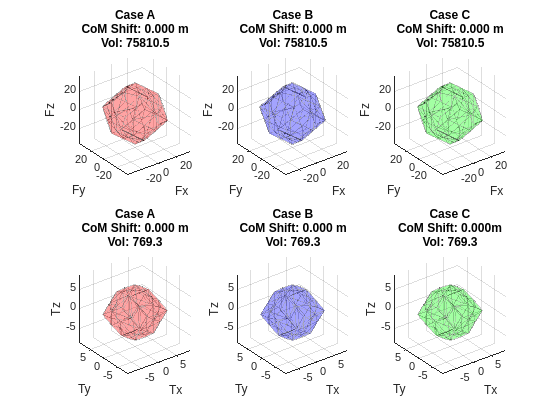

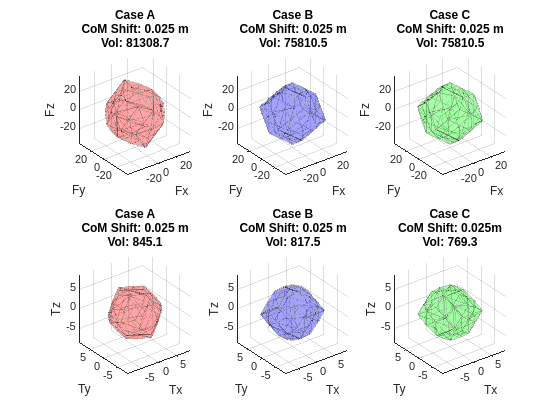

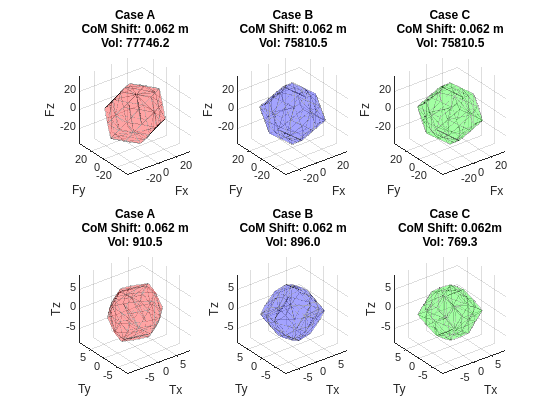

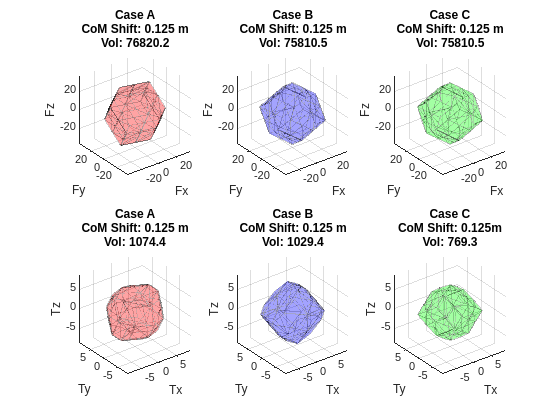

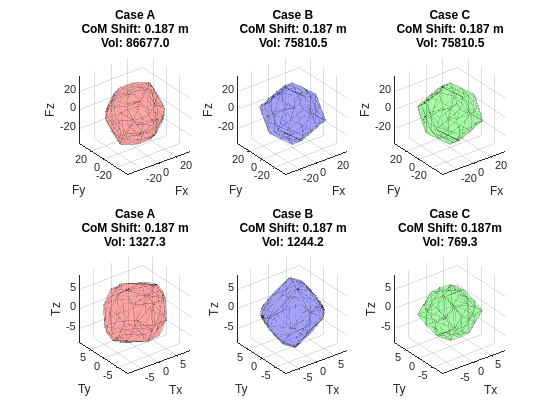

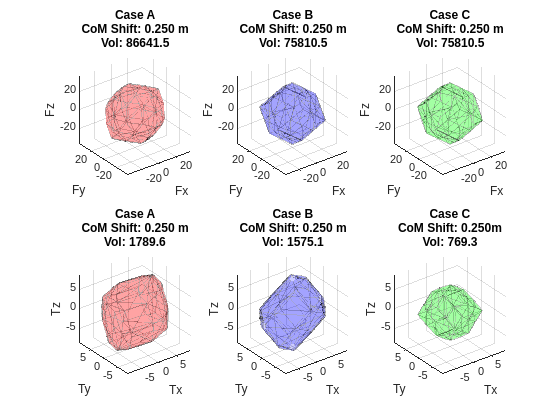

hFig = figure('Name', 'Polytope Evolution', 'Color', 'w', 'Position', [100, 100, 1200, 500]);
max_F = 0;
max_T = 0;
for j = 1:num_scenarios
    % Stima rapida max force
    pi_A = pi_B_Bcom_all(:,:,j); N_A = N_all(:,:,j);
    if k==1, Bt=AllocationMatrixBrescianini(N_A, pi_A); else, Bt=AllocationMatrixTilt(N_A, pi_A); end
    F_check = Bt(1:3,:) * U_poly;
    max_F = max(max_F, max(abs(F_check(:))));
    T_check = Bt(4:6,:) * U_poly;
    max_T = max(max_T, max(abs(T_check(:))));
end

ax_lim_F = [-max_F, max_F] * 1.1; 
ax_lim_T = [-max_T, max_T] * 1.1; 

for j = 1 : size(CoM_all,2) 
   
    CoM_c = CoM_all(:, j);
    
    % A. Adaptive
    pi_A = pi_B_Bcom_all(:,:,j); 
    N_A  = N_all(:,:,j);
    if k==1, B_A=AllocationMatrixBrescianini(N_A, pi_A); else, B_A=AllocationMatrixTilt(N_A, pi_A); end
    
    % B. Non Adaptive
    N_B  = N_all(:,:,1);
    pi_B = pi_B_Bcom_all(:,:,j); 
    if k==1, B_B=AllocationMatrixBrescianini(N_B, pi_B); else, B_B=AllocationMatrixTilt(N_B, pi_B); end

    % C. Fixed
    N_C  = N_all(:,:,1);
    pi_C = pi_B_Bcom_all(:,:,1); 
    if k==1, B_C=AllocationMatrixBrescianini(N_C, pi_C); else, B_C=AllocationMatrixTilt(N_C, pi_C); end
    
    % Calcolo Nuvole Punti
    F_A = B_A(1:3, :) * U_poly;
    F_B = B_B(1:3, :) * U_poly;
    F_C = B_C(1:3, :) * U_poly;
    T_A = B_A(4:6, :) * U_poly;
    T_B = B_B(4:6, :) * U_poly;
    T_C = B_C(4:6, :) * U_poly;
    
    % Calcolo Hull
    [k_F_A, v_F_A] = convhull(F_A(1,:), F_A(2,:), F_A(3,:));
    [k_F_B, v_F_B] = convhull(F_B(1,:), F_B(2,:), F_B(3,:));
    [k_F_C, v_F_C] = convhull(F_C(1,:), F_C(2,:), F_C(3,:));
    [k_T_A, v_T_A] = convhull(T_A(1,:), T_A(2,:), T_A(3,:));
    [k_T_B, v_T_B] = convhull(T_B(1,:), T_B(2,:), T_B(3,:));
    [k_T_C, v_T_C] = convhull(T_C(1,:), T_C(2,:), T_C(3,:));
    
    % --- PLOT ADAPTIVE ---
    fig = figure;
    subplot(2,3,1);
    trisurf(k_F_A, F_A(1,:), F_A(2,:), F_A(3,:), 'FaceColor', 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'k', 'EdgeAlpha', 0.2);
    axis equal; grid on; view(3);
    xlim(ax_lim_F); ylim(ax_lim_F); zlim(ax_lim_F);
    title({['Case A'], ...
           ['CoM Shift: ' num2str(results.com_dist(j), '%.3f') ' m'], ...
           ['Vol: ' num2str(v_F_A, '%.1f')]});
    xlabel('Fx'); ylabel('Fy'); zlabel('Fz');

    % --- PLOT FIXED ---
    subplot(2,3,2);
    trisurf(k_F_B, F_B(1,:), F_B(2,:), F_B(3,:), 'FaceColor', 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'k', 'EdgeAlpha', 0.2);
    axis equal; grid on; view(3);
    xlim(ax_lim_F); ylim(ax_lim_F); zlim(ax_lim_F);
    title({['Case B'], ...
           ['CoM Shift: ' num2str(results.com_dist(j), '%.3f') ' m'], ...
           ['Vol: ' num2str(v_F_B, '%.1f')]});
    xlabel('Fx'); ylabel('Fy'); zlabel('Fz');

    subplot(2,3,3);
    trisurf(k_F_C, F_C(1,:), F_C(2,:), F_C(3,:), 'FaceColor', 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'k', 'EdgeAlpha', 0.2);
    axis equal; grid on; view(3);
    xlim(ax_lim_F); ylim(ax_lim_F); zlim(ax_lim_F);
    title({['Case C'], ...
           ['CoM Shift: ' num2str(results.com_dist(j), '%.3f') ' m'], ...
           ['Vol: ' num2str(v_F_C, '%.1f')]});
    xlabel('Fx'); ylabel('Fy'); zlabel('Fz');
    
     % --- PLOT ADAPTIVE ---
    subplot(2,3,4);
    trisurf(k_T_A, T_A(1,:), T_A(2,:), T_A(3,:), 'FaceColor', 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'k', 'EdgeAlpha', 0.2);
    axis equal; grid on; view(3);
    xlim(ax_lim_T); ylim(ax_lim_T); zlim(ax_lim_T);
    title({['Case A'], ...
           ['CoM Shift: ' num2str(results.com_dist(j), '%.3f') ' m'], ...
           ['Vol: ' num2str(v_T_A, '%.1f')]});
    xlabel('Tx'); ylabel('Ty'); zlabel('Tz');

    % --- PLOT FIXED ---
    subplot(2,3,5);
    trisurf(k_T_B, T_B(1,:), T_B(2,:), T_B(3,:), 'FaceColor', 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'k', 'EdgeAlpha', 0.2);
    axis equal; grid on; view(3);
    xlim(ax_lim_T); ylim(ax_lim_T); zlim(ax_lim_T);
    title({['Case B'], ...
           ['CoM Shift: ' num2str(results.com_dist(j), '%.3f') ' m'], ...
           ['Vol: ' num2str(v_T_B, '%.1f')]});
    xlabel('Tx'); ylabel('Ty'); zlabel('Tz');

    subplot(2,3,6);
    trisurf(k_T_C, T_C(1,:), T_C(2,:), T_C(3,:), 'FaceColor', 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'k', 'EdgeAlpha', 0.2);
    axis equal; grid on; view(3);
    xlim(ax_lim_T); ylim(ax_lim_T); zlim(ax_lim_T);
    title({['Case C'], ...
           ['CoM Shift: ' num2str(results.com_dist(j), '%.3f') 'm'], ...
           ['Vol: ' num2str(v_T_C, '%.1f')]});
    xlabel('Tx'); ylabel('Ty'); zlabel('Tz');

    set(fig, 'PaperUnits','centimeters', 'PaperSize', [W H], ...
                 'PaperPosition',[m m W-2*m H-2*m]);
    fileName = fullfile(outputFolder, sprintf('Polytope_Case_CoM_%d.pdf',j));
    print(fig, fileName, '-dpdf', '-vector');    
end

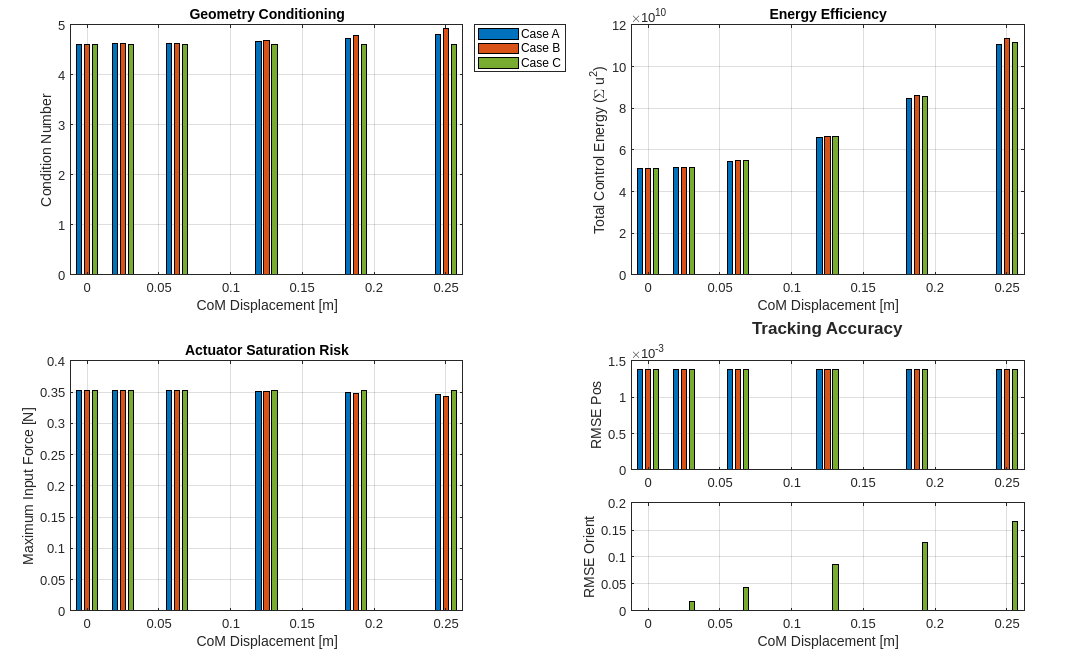

% Ordiniamo i risultati in base alla distanza del CoM per pulizia nei grafici
[sorted_dist, sort_idx] = sort(results.com_dist);

% Estrazione array ordinati
R_rmse_A_s = results.R_rmse_A(sort_idx); R_rmse_B_s = results.R_rmse_B(sort_idx); R_rmse_C_s = results.R_rmse_C(sort_idx);
p_rmse_A_s = results.p_rmse_A(sort_idx); p_rmse_B_s = results.p_rmse_B(sort_idx); p_rmse_C_s = results.p_rmse_C(sort_idx);
ener_A_s = results.energy_A(sort_idx); ener_B_s = results.energy_B(sort_idx); ener_C_s = results.energy_C(sort_idx);
maxu_A_s = results.max_u_A(sort_idx); maxu_B_s = results.max_u_B(sort_idx); maxu_C_s = results.max_u_C(sort_idx);
cond_A_s = results.cond_A(sort_idx); cond_B_s = results.cond_B(sort_idx); cond_C_s = results.cond_C(sort_idx);
maxf_A_s = results.max_f_A(sort_idx); maxf_B_s = results.max_f_B(sort_idx); maxf_C_s = results.max_f_C(sort_idx);

% Limite saturazione
fig = figure('Name','Comparative Analysis (Bar Charts)', ...
       'Color','w', ...
       'Units','normalized', ...
       'Position',[0.1 0.1 0.82 0.78]);

colors = [0 0.4470 0.7410;      % Blue  (Case A)
          0.8500 0.3250 0.0980; % Red   (Case B)
          0.4660 0.6740 0.1880];% Green (Case C)
fontSize = 10;
barWidth = 0.7;
t_main = tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

%% --- 1. Condition Number ---
nexttile(t_main,1)
data_cond = [cond_A_s(:), cond_B_s(:), cond_C_s(:)];
b1 = bar(sorted_dist, data_cond, barWidth, 'FaceColor','flat');
for i = 1:3, b1(i).CData = colors(i,:); end

xlabel('CoM Displacement [m]')
ylabel('Condition Number')
title('Geometry Conditioning')
legend({'Case A','Case B','Case C'},'Location','bestoutside')
grid on
set(gca,'FontSize',fontSize)

%% --- 2. Control Effort (Energy) ---
nexttile(t_main,2)
data_ener = [ener_A_s(:), ener_B_s(:), ener_C_s(:)];
b2 = bar(sorted_dist, data_ener, barWidth, 'FaceColor','flat');
for i = 1:3, b2(i).CData = colors(i,:); end

xlabel('CoM Displacement [m]')
ylabel('Total Control Energy (\Sigma u^2)')
title('Energy Efficiency')
grid on
set(gca,'FontSize',fontSize)

%% --- 3. Actuator Saturation (Max Input) ---
nexttile(t_main,3)
data_maxf = [results.sigma_A(:), results.sigma_B(:), results.sigma_C(:)];
b3 = bar(sorted_dist, data_maxf, barWidth, 'FaceColor','flat');
for i = 1:3, b3(i).CData = colors(i,:); end
xlabel('CoM Displacement [m]')
ylabel('Maximum Input Force [N]')
title('Actuator Saturation Risk')
grid on
set(gca,'FontSize',fontSize)

%% --- 4. Tracking RMSE (nested: Position + Orientation) ---
t_rmse = tiledlayout(t_main,2,1,'TileSpacing','compact','Padding','compact');
t_rmse.Layout.Tile = 4;

title(t_rmse,'Tracking Accuracy','FontWeight','bold')

% ---- 4a. RMSE Position ----
nexttile(t_rmse,1)
data_rmse_pos = [p_rmse_A_s(:), p_rmse_B_s(:), p_rmse_C_s(:)];
b4a = bar(sorted_dist, data_rmse_pos, barWidth, 'FaceColor','flat');
for i = 1:3, b4a(i).CData = colors(i,:); end

ylabel('RMSE Pos')
grid on
set(gca,'FontSize',fontSize)

% ---- 4b. RMSE Orientation ----
nexttile(t_rmse,2)
data_rmse_ori = [R_rmse_A_s(:), R_rmse_B_s(:), R_rmse_C_s(:)];
b4b = bar(sorted_dist, data_rmse_ori, barWidth, 'FaceColor','flat');
for i = 1:3, b4b(i).CData = colors(i,:); end

xlabel('CoM Displacement [m]')
ylabel('RMSE Orient')
grid on
set(gca,'FontSize',fontSize)
set(fig, 'PaperUnits','centimeters', 'PaperSize', [W H], ...
                 'PaperPosition',[m m W-2*m H-2*m]);
fileName = fullfile(outputFolder, sprintf('Cases_Analysis.pdf'));
print(fig, fileName, '-dpdf', '-vector'); 